clear;
%%STOP!!
data_stop = readtable('stop.txt', 'ReadVariableNames', false);
data_stop = data_stop.Var1; % Assuming the data is in the first column
% 
% % Plot the histogram
figure;
bordes = -0.5:1:356.5;
h = histogram(data_stop, bordes)

h =   Histogram with properties:

             Data: [10240×1 double]
           Values: [1×357 double]
          NumBins: 357
         BinEdges: [1×358 double]
         BinWidth: 1
        BinLimits: [-0.5000 356.5000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


bines = h.BinCounts

bines =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    64     0    69     0    29     0    69     0    91     0    58     0    60     0    56     0    47     0



title('Stop');
xlabel('Bin');
ylabel('Frequency');

% Save the plot as an image file (optional)
saveas(gcf, 'stop_histogram.png');

%%PROCESSING DATA
maxbin = max(find(bines, 1, 'last'))

maxbin = 349

minbin = min(find(bines, 1, 'first'))

minbin = 33


N_cells = maxbin-minbin

N_cells = 316

N = length(data_stop)

N = 10240

T = 1/(200e6)

T = 5.0000e-09

resolucion = T/N_cells

resolucion = 1.5823e-11


tau_med = T/N_cells

tau_med = 1.5823e-11

tau_i   = bines*(T/N)

tau_i = 	1.0e+-10 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.3125         0    0.3369         0    0.1416         0    0.3369         0    0.4443         0    0.2832         0    0.2930         0    0.2734         0    0.2295         0


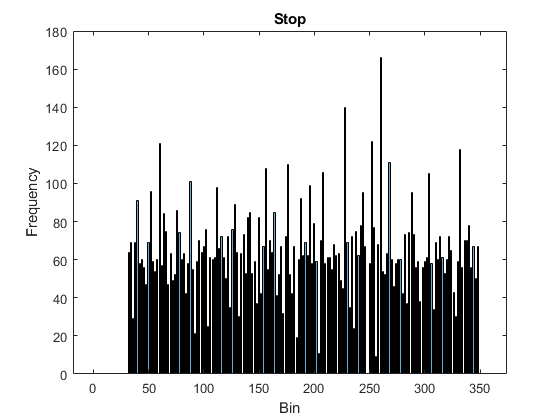


tiledlayout(3,1)


%Ps histogram
nexttile
bar(tau_i)
ax = gca;
ax.YAxis.Exponent = -12;
ylabel('ps'); xlabel('bin');

%DNL
nexttile
dnl_i = (tau_i - tau_med)/resolucion

dnl_i =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000    0.9750   -1.0000    1.1293   -1.0000   -0.1051   -1.0000    1.1293   -1.0000    1.8082   -1.0000    0.7898   -1.0000    0.8516   -1.0000    0.7281   -1.0000    0.4504   -1.0000


dnl_i(1, 1:minbin)   = 0;
dnl_i(1, maxbin:end) = 0;
bar(dnl_i)
ylabel('LSB'); xlabel('bin'); title('DNL')

%INL
nexttile
inl_i = cumsum(dnl_i);
bar(inl_i);
ylabel('LSB'); xlabel('bin'); title('INL')

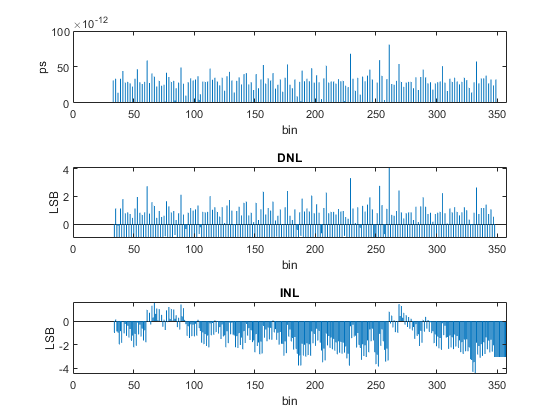


saveas(gcf, 'histo_dnl_inl.png');


resultados = load('resultados.txt')

resultados =    300   306    20
   302   310    20
   304   312    20
   306   316    20
   310   318    20
   312   320    20
   316   324    20
   318   326    20
   320   326    20
   322   331    20


resultados_stop = resultados(:,1)

resultados_stop =    300
   302
   304
   306
   310
   312
   316
   318
   320
   322


resultados_start = resultados(:,2)

resultados_start =    306
   310
   312
   316
   318
   320
   324
   326
   326
   331


resultados_coarse = resultados(:,3)

resultados_coarse =     20
    20
    20
    20
    20
    20
    20
    20
    20
    20



t_medido = resultados_coarse*T + (resultados_stop-resultados_start)*tau_med

t_medido = 	1.0e+-6 *

    0.0999
    0.0999
    0.0999
    0.0998
    0.0999
    0.0999
    0.0999
    0.0999
    0.0999
    0.0999


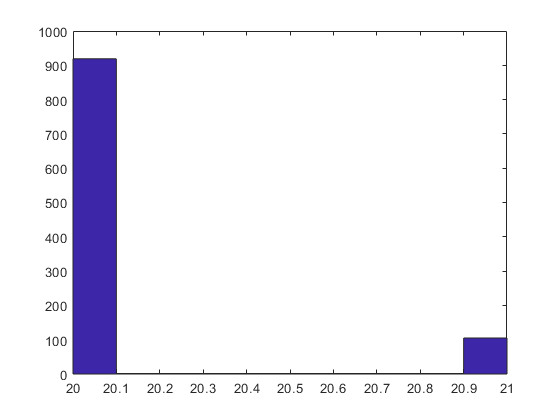


clf;
figure;
hist(resultados_coarse)

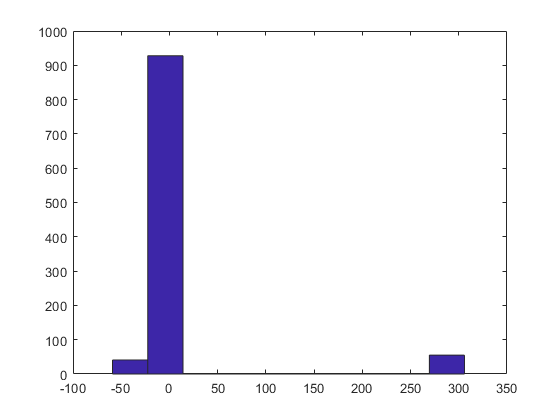


clf;
figure;
hist(resultados_stop-resultados_start)

figure;

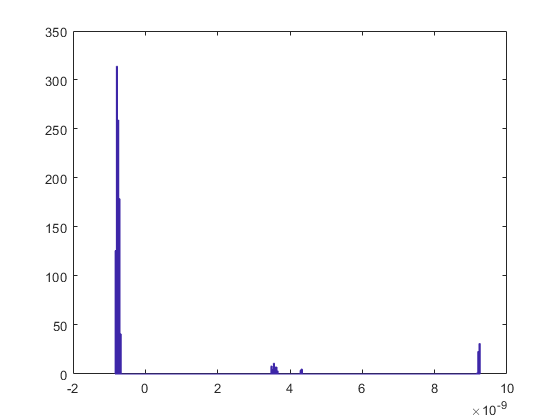


% bines = linspace()
hist(t_medido-mean(t_medido), 300)
ax = gca;
ax.XAxis.Exponent = -9;


indices_coarse_malos = find(resultados_coarse==21)

indices_coarse_malos =     15
    16
    17
    18
    19
    20
    21
    22
    23
    24


t_medido = resultados_coarse(indices_coarse_malos)*T + (resultados_stop(indices_coarse_malos)-resultados_start(indices_coarse_malos))*tau_med

t_medido = 	1.0e+-6 *

    0.1049
    0.1049
    0.1098
    0.1098
    0.1098
    0.1098
    0.1098
    0.1042
    0.1042
    0.1042


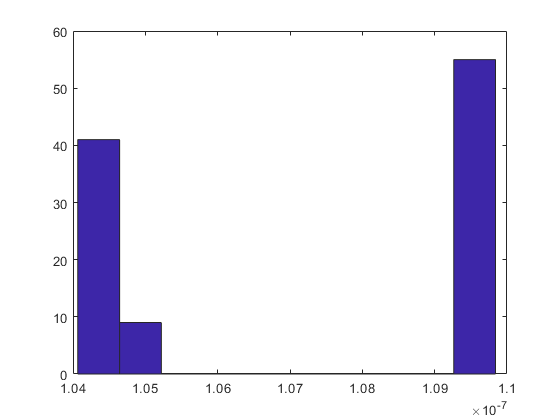

hist(t_medido)

std(t_medido)

ans = 2.7747e-09

length(find(t_medido>1.05e-7))

ans = 55

%%START!!
data_start = readtable('start.txt', 'ReadVariableNames', false);
data_start = data_start.Var1; % Assuming the data is in the first column
% 
% % Plot the histogram
figure;
bordes = -0.5:1:356.5;
h = histogram(data_start, bordes);
h.BinCounts

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    89    11    51     2    53     6    64     0    74     7    62     0    22    29    49     1    88     0    74     0    50     8    61     0    36    16


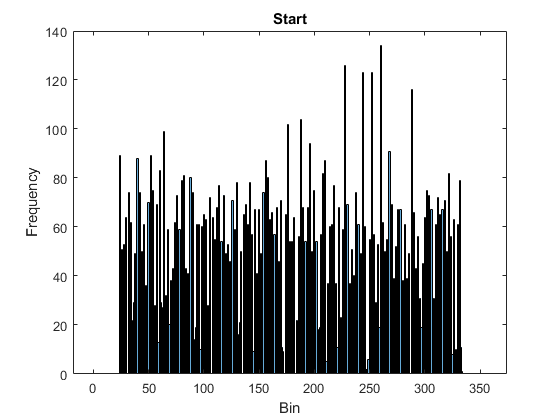

title('Start');
xlabel('Bin');
ylabel('Frequency');

% Save the plot as an image file (optional)
saveas(gcf, 'start_histogram.png');